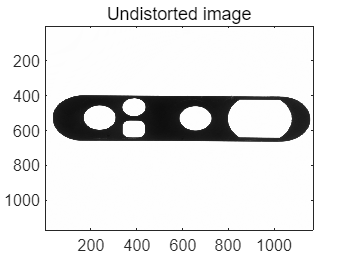

load matlab_calib.mat;%加载标定的参数结果
intrinx = cameraParams.IntrinsicMatrix;
I2=imread("new_image.png");

fx = intrinx(1,1);
fy = intrinx(2,2);
fc = [fx fy];
cx = intrinx(1,3);
cy = intrinx(2,3);
cc = [cx cy];
alpha_c = 0;
k21 = cameraParams.RadialDistortion(1);
k22 = cameraParams.RadialDistortion(2);
k23 = 0;
p21=cameraParams.TangentialDistortion(1);
p22=cameraParams.TangentialDistortion(2);

[H,W] = size(I2);%图像尺寸
W=1171;
I22 = 255*zeros(H,W);%创建去畸变图像尺寸

for x=1:H 
    for y=1:W  
    %图像像素坐标系转换到相机坐标系
        yy=(y-cy)/fy; 
        xx=(x-cx)/fx;
    %在相机坐标系中做去畸变
        r=xx^2+yy^2;
        xxx=xx*(1+k21*r+k22*r^2+k23*r^3)+2*p21*xx*yy+p22*(r+2*xx^2);
        yyy=yy*(1+k21*r+k22*r^2+k23*r^3)+2*p22*xx*yy+p21*(r+2*yy^2);
    %去畸变后重新将相机坐标系转换到图像像素坐标系
        xxxx=xxx*fx+cx;
        yyyy=yyy*fy+cy;
        if (xxxx>1 && xxxx<=W && yyyy>1 && yyyy<=H)
            h=yyyy;
            w=xxxx;
           %用源图像的像素值对新图像的像素点进行插值
            I22(y,x)=(floor(w+1)-w)*(floor(h+1)-h)*I2(floor(h),floor(w))+...
                (floor(w+1)-w)*(h-floor(h))*I2(floor(h+1),floor(w))+(w-floor(w))*...
                (floor(h+1)-h)*I2(floor(h),floor(w+1))+(w-floor(w))*(h-floor(h))*I2(floor(h+1),floor(w+1));
        end
    end
end   
imwrite(uint8(I22),'undistort.png')
figure();
image(I22);
colormap(gray(256));
title('Undistorted image');